Reference ; "Exploring ODE,..."

**4. Second-order ODEs and,..**

**4.1 Simple problem**

 consider a homogeneous 2nd ODE


$$y" + \omega^2 y = 0$$


The solution is 


$$Ae^{i\omega t } + B e^{-i\omega t} $$


If the initial consditions are


$$y(0) = 1 \ y'(0) = 1$$


Then two unknowns are determined by two initial (boundary) conditions, assuming $\omega = 1$; 

clear all; clc
LW = 'linewidth';
L = chebop(0,60); % with interval
L.op =@(t,y) diff(y,2) + y; % specific ODE
L.lbc=[1;0];  % boundary conditions
y =L\0;       % homogeneous 
plot(y,LW,2); grid on

Here the function "chebop" is a tool, if you need to know it, 

doc chebop

Then "matlab' provide you with what it is.If ODE is 


$$y" + 0.1y'+ \omega ^2 y = 0$$


Then the code is

L.op = @(t,y) diff(y,2) + 0.1*diff(y) + y;
y = L\0; 
plot(y,LW,2); grid on

4.2 Time reverse differential equation

**5. Boundary - value problems in One varaible**

**5.1 introduction**

Here are ODE's with the initial condtions as well as the final conditions,i.e.,boundary conditions. The initial condition is same to the left boiundary and the final as the rigth boundary vice versa. 

Consider  a boundary value problem as


$$y" = -y, \ x \in [0,60], \\ y(0) = 1, y(60)= 0$$


This is two boundary value problem, since initail and the final values at each time. The code is

clear all; clc;
LW ='linewidth';
D = [0, 60];
L = chebop(D);
L.op=@(x,y) diff(y,2)+ y;
L.lbc =1;
L.rbc =0;
y= L\0;
plot(y,LW,2)

If  this numerical soution may be needed to be verified, 

ys = y;
plot(diff(ys,2)+ys);  % dynamic equation
[ys(0) ys(60)]

If you need these results more accutr=rately, you may do it.

**5.2 inhomogeneous and various B.C.'s**

see the following


$$y" = y + (x-20)/20 \\
x\in [0,60], y(0) =0,\ y(60) = 0$$


The oarticular solution is  $y_p(t)  = -(x-20)/20$.

The code is

clear all; clc;
LW ='linewidth';
D = [0, 60];
L = chebop(D);
L.op =@(x,y) diff(y,2)-y;
L.lbc =0; L.rbc = 0;
x = chebfun(@(x) x, D);
rhs = (x-20)/20;
y = L\rhs;
plot(y,LW,2);grid on

If the boudary is given by derivatives, in general , "Neumann Condition" as


$$y'(60) = 0$$


clear all; clc;
LW ='linewidth';
D = [0, 60];
L = chebop(D);
L.op =@(x,y) diff(y,2)-y;
L.lbc =0; L.rbc = @(y) diff(y);
x = chebfun(@(x) x, D);
rhs = (x-20)/20;
y = L\rhs;
plot(y,LW,2); grid on

**5.2 matlab "bvp4c" for two point BVP**

In matlab, there is a function for Boundary value problems as "bvp4c"  . If you type in the command window

doc bvp4c

Here 

`sol = bvp4c(odefun,bcfun,solinit)`

Here to use bvp4c, you need to define

- odefun : the specific ode you want to solve

-bcfun : boundary defined 

-solinit: to initialize to solve 

In matlab, they introduce "mesh" as a small interval(or area) to satisftg the ode and BC's.

Let us an example


$$y" + y = 0 , x \in [0 \ \pi/2] \\ y(0) = 0, \ y(\pi /2) = 2
$$


So the inital and the final conditions. Now you should change this to the " equivalent" state space model

1) first; to derive  the "equivalent " state space model.


$$y_1 ' = y_2 \\
y_2 ' = -y_1 $$


 the code is 

f = @(x,y) [y(2) ; -y(1)];  % state space

2) second: define the boundary function

Here the boundary is 


$$ y(0) = 0, \ y(\pi /2) = 2
$$


which is in state space


$$y(1)(t=0) =0, \ y(1)(t=\pi/2) = 2$$


the code is 

bc = @(ya,yb) [ya(1); yb(1)];

which is a little bit confused. However, here $(a,b)$ = (initial time, final time) or (left bc , right bc). and $ya(1)$ means y(1) at time $t=a $ or the left position and $yb(1)$ means $y(1) $ at time $t=b$ or the right position.

3) select the time step(or meshgrid) and  the initial guess

At the first point in $(y(1)(t=0),y(2)(t=0))  == (0,1)$meshgrid,  

the code as

solinit = bvpinit(xmesh, [1 0]);

All together are 

clear all; clc
LW = 'linewidth';
f = @(x,y) [y(2) ; -y(1)];  % state space
bc = @(ya,yb) [ya(1); yb(1)-2];

xmesh = linspace(0, pi/2, 10);
solinit = bvpinit(xmesh, [1 0]);
sol = bvp4c(f, bc, solinit);
% plot(sol.x, sol.y(1,:)); grid on
figure(1)
plot(sol.x, sol.y,'-o', LW,2); grid on
% for y(1) plotting
figure(2)
plot(sol.x, sol.y(1,:), LW,2); grid on

For BC verification, at the initial and final values are equivalent to the given values. 

**5.3 Using chebfun **

Here is simpler than the bvp4c. 

clear all; clc;clf
LW = 'linewidth';
D =[0, pi/2];
L =chebop(D); L.lbc =0; L.rbc =2;
L.op =@(t,x) diff(x,2)+x;
x=L\0;
plot(x,LW,2); grid on

Here it may not need to chage into a state space form as well as simple(understandable!!) boundary condition descriptions.

- **HW_Week_5_1**

Given the ODE 


$$y" + \frac{2}{x}y' + \frac{1}{x^4}y =0, \ x \in [\frac{1}{3\pi }, \ 1]\\
y(\frac{1}{3\pi }) = 0, y(1) = sin(1),  $$


1) code to find a numerical solution using "bvp4c" and compare it with the analytic solution.

2) code using "chebfun" and compare it with the analytic solution

 **  the analytic solution is 

   
$$y= sin(1/x)$$
     

                                                                           QED

**10. Sytems of Equation - Multivariables  - using chebfun **

**10.1 Linear systems-IVP**

Here we may consider systems of equations with multiple independent variables. Consider a system ODE , $t \in [0, \ 30]$


$$u' = -v \\ v' = u$$


with the boundary conditions 


$$u(0)=1, \ v(0) = 0;$$


then to get a numerical solutions,the code may be

clear all; clc;
LW = 'linewidth'; 
D = [0,30];
N = chebop(D);
N.op = @(t,u,v) [diff(u)+v; diff(v)-u];
N.lbc =[1;0];
[u,v] = N\0;
plot([u,v], LW,2); grid on

- **HW_Week_5_2**

1) Find the analytic solution to the previous system equation

2) To compare the numerical solution and the analytic solutions, plot the analytic and the numerical ones.

                                                                        QED

**10.2 Non-linear sytems-IVP**

In system  ODE, regarding to boundary conditions, two subjects are 

1)**IVP** : initial value problem.the conditions are specified at the same time( not only time, or space), this is the general cases as you see in many problems 

2)**BVP**: the conditions are specified at the different time. You see in the "optimal control", the costate dynamics are governed by "backward" which means the final values are specified. to solve these 'backwad" equation, one method is to define a new" backward" time and then reverse time scale to get the solution to the backward equation. In our textbook, "Optimal,..."  in Chap.3.2 , " Solution of Two-Point Boundary- value problems". The prescribed methods are complex. Why? The existence of the solution to IVP is well-defined , however, BVP is not well defined.(see 

ODE, p 116). The solution may not exist or many solutions are there. hence everytime, YOU SHOULD verify the numerical solution's accuracy. Still BVP is not well posed(In matlab bvp4c or bvp5c gives a absurd  solution in some BVP(Sometimes in YOUTUBE!!)

Now we may consider a nonlinear system as


$$u' = -v -u)u^2 + v^2 \\ v' = u -v(u^2 + v^2)$$


with the boundary conditions 


$$u(0)=1, \ v(0) = 0;$$


the code may be 

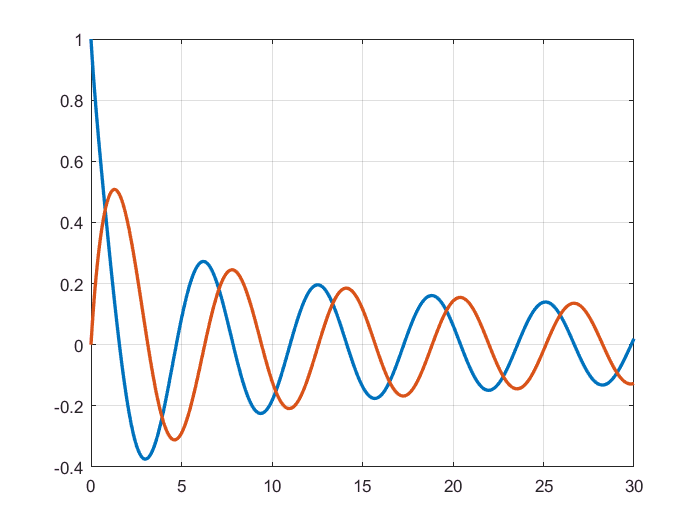

clear all; clc;
LW = 'linewidth'; 
D = [0,30];
N = chebop(D);
N.op = @(t,u,v) [diff(u)+v+u*(u^2+v^2); diff(v)-u+v*(u^2 + v^2)];
N.lbc =[1;0];
[u,v] = N\0;
plot([u,v], LW,2); grid on

**There are a lot of examples to be interested in the Book. The simplicity of code is wonderful, However almost all IVP...unfortunately..**